# **Sesión 2.1. - Determinación de la matriz de transformación homogénea utilizando Denavit-Hartenberg **

- Objetivo: Encontrar una matriz de transformación homogénea T que relacione la posición y orientación del extremo del robot con respecto a un sistema de referencia fijo situado en su base

- Matriz ${}^{i-1}A_i$: matriz de transforación homogénea que representa la posición y orientación relativa entre los sistemas asociados a dos eslabones consecutivos del robot

- Matriz T: matriz 0An cuando se consideran todos los grados de libertad del robot

    
$$T=^0 A_n =$$

$${}^0A_1\;\;{}^1A_2\;\;{}^2A_3\ldotp \ldotp \ldotp {}^{n-1}A_n$$


- Denavit-Hartenberg propusieron en 1955 un método matricial que permite establecer de manera sistemática un sistema de coordenadas (*Si*) ligado a cada eslabón *i *de una cadena articulada, pudiéndose determinar a partir de él, el modelo cinemático del robot.

- Según la representación D-H, escogiendo adecuadamente los sistemas de coordenadas asociados para cada eslabón, será posible pasar de un sistema de coordenadas al siguiente, mediante **4 transformaciones básicas **que dependen exclusivamente de las características geométricas del eslabón.

- Estas transformaciones básicas consisten en una sucesión de rotaciones y traslaciones que permitan relacionar el sistema de coordenadas del eslabón *i *con el eslabón *i-1*  

- Transformaciones básicas de paso de eslabón (definidas sobre sistema móvil -> postmultiplicar): 

                    – Rotación alrededor del eje $z_{i-1}$ un ángulo θi

                    – Traslación a lo largo de zi una distancia di ; vector di (0,0,di)

                    – Traslación a lo largo de xi una distancia ai ; vector ai (0,0,ai)

                    – Rotación alrededor del eje x i un ángulo ai  

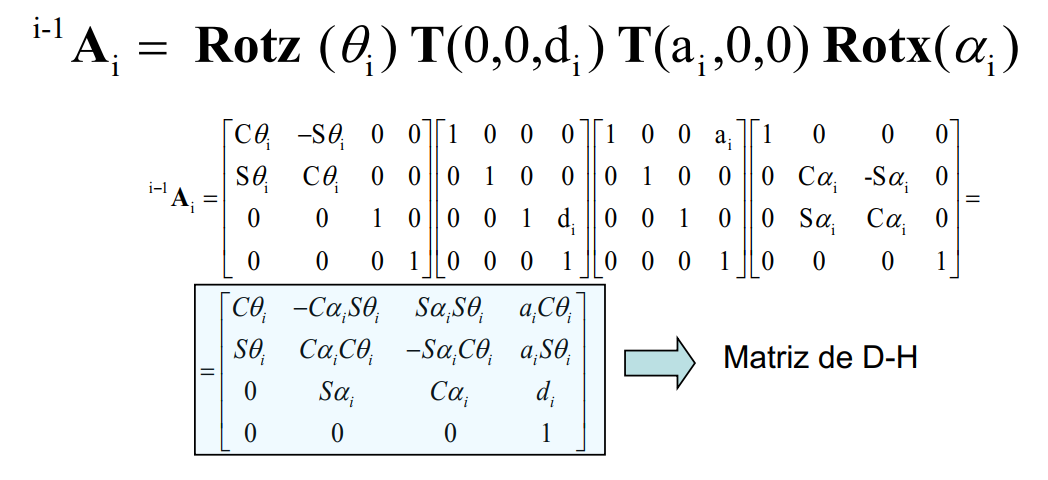

Ejemplo para un robot planar de 2gdl. Parámetros geométricos del robot son : a1 = 20; a2 = 10; theta1 =0; theta2= pi/2;

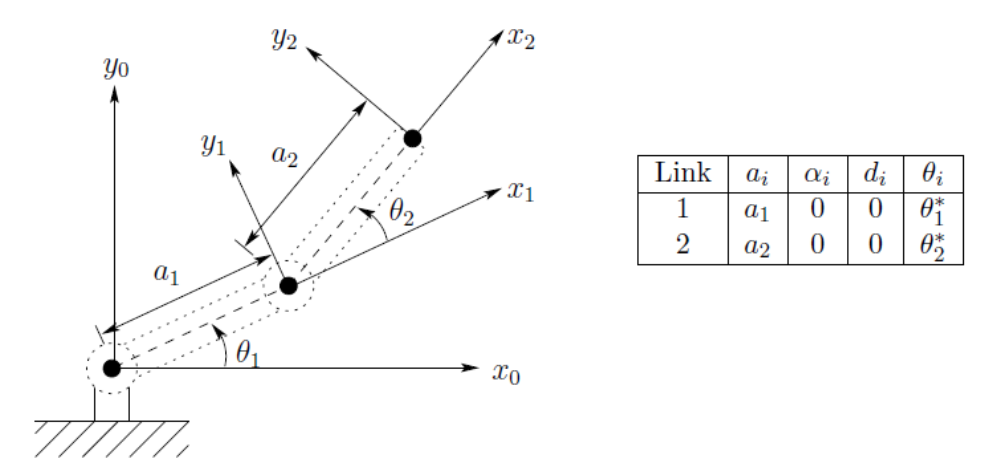

## 1.- Determinación mediante la definición de los parámetros DH

El comando [syms](https://es.mathworks.com/help/symbolic/syms.html?searchHighlight=syms&s_tid=srchtitle_syms_1) de Matlab permite crear variables simbólicas.Vamos a determinar la matriz de transformación homogénea de manera simbólica, a partir de su definición:

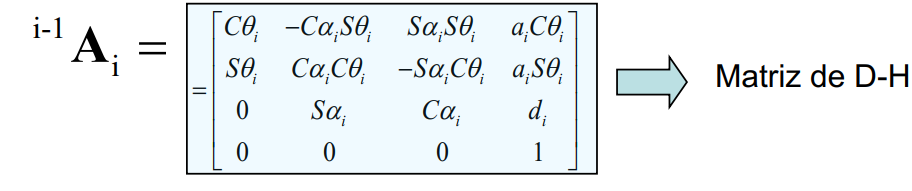

syms a1 a2 theta1 theta2
alphaa = [0,0]; % this is the alpha value for all  the link
a=[a1, a2]; % Length of the Link
d=[0,0]; %Offset
thethaa=[theta1,theta2]; % joint angle variation
%% Transformation Matrices
for i = 1:2
    switch i
        case 1
           T01= [cos(thethaa(1,i)),-sin(thethaa(1,i))*cos(alphaa(1,i)),sin(alphaa(1,i))*sin(thethaa(1,i)),a(1,i)*cos(thethaa(1,i));sin(thethaa(1,i)),cos(thethaa(1,i)).*cos(alphaa(1,i)),-sin(alphaa(1,i))*cos(thethaa(1,i)),sin(thethaa(1,i))*a(1,i);0,sin(alphaa(1,i)),cos(alphaa(1,i)),d(1,i);0,0,0,1];
        case 2
            T12= [cos(thethaa(1,i)),-sin(thethaa(1,i))*cos(alphaa(1,i)),sin(alphaa(1,i))*sin(thethaa(1,i)),a(1,i)*cos(thethaa(1,i));sin(thethaa(1,i)),cos(thethaa(1,i)).*cos(alphaa(1,i)),-sin(alphaa(1,i))*cos(thethaa(1,i)),sin(thethaa(1,i))*a(1,i);0,sin(alphaa(1,i)),cos(alphaa(1,i)),d(1,i);0,0,0,1];
    end
end

T01 % First Link with respect to base

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12% Second Link with respect to base  

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = T01*T12;
%% You can simplify it too
simplify(T02)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Con la función subs, se puede evaluar el valor de la solución obtenida. 

Parámetros del sistema a1 = 20; a2 = 10; theta1 = 0; theta2 = 90º

a1 = 20;
a2 = 10;
theta1 =0;
theta2= pi/2;
subs(T02)

$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & 20\\ 1 & 0 & 0 & 10\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## **2.- Determinación mediante la multiplicación de las 4 transformaciones básicas**

Vamos a calcular la matriz de transformación homogénea mediante la multiplicación de 4 transformaciones básicas.

La función [makehgtform](https://es.mathworks.com/help/matlab/ref/makehgtform.html?searchHighlight=makehgtform&s_tid=srchtitle_makehgtform_1) crea una matriz de transformación homogénea 4x4 de transformación, escalado o rotación. 

nT01 = makehgtform('zrotate',0) * makehgtform('translate',[a1 0 0])
nT12 = makehgtform('zrotate',theta2) * makehgtform('translate',[a2 0 0])

nT01 =      1     0     0    20
     0     1     0     0
     0     0     1     0
     0     0     0     1


nT02 = nT01 *nT12

nT12 =      0    -1     0     0
     1     0     0    10
     0     0     1     0
     0     0     0     1


nT02 =      0    -1     0    20
     1     0     0    10
     0     0     1     0
     0     0     0     1
